# Tutorial 2

## Funciones de singularidad

delta = @(n) n==0;
u = @(t) t>=0;
r = @(t) t.*u(t);


$$\frac{d}{\textrm{dt}}u\left(t\right)=\delta \left(t\right)$$


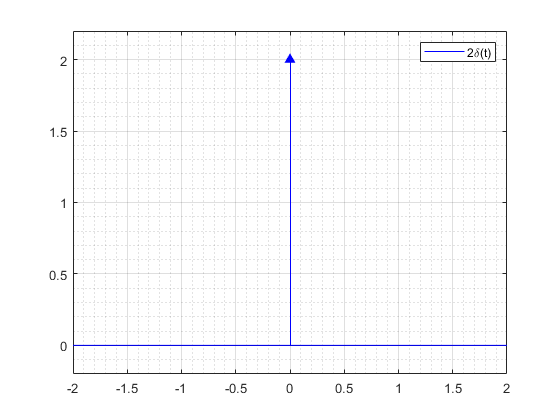

t = -2:0.001:2;
figure(1)
clf
plot(t,0.*t,'b');
hold on
grid on
grid minor
legend({'2\delta(t)'})
stem(0,2,'b^','filled','HandleVisibility',"off")
ylim([-0.2,2.2])

### Representar funciones a trozos como funciones de singularidad

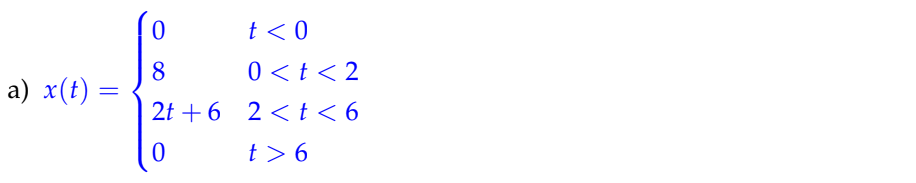


$$x\left(0^- \right)=0$$
                            
$$x\left(0^+ \right)=8$$



$$x\left(2^- \right)=8$$
                            
$$x\left(2^+ \right)=2\left(2\right)+6=10$$



$$x\left(6^- \right)=2\left(6\right)+6=18$$
        
$$x\left(6^+ \right)=0$$


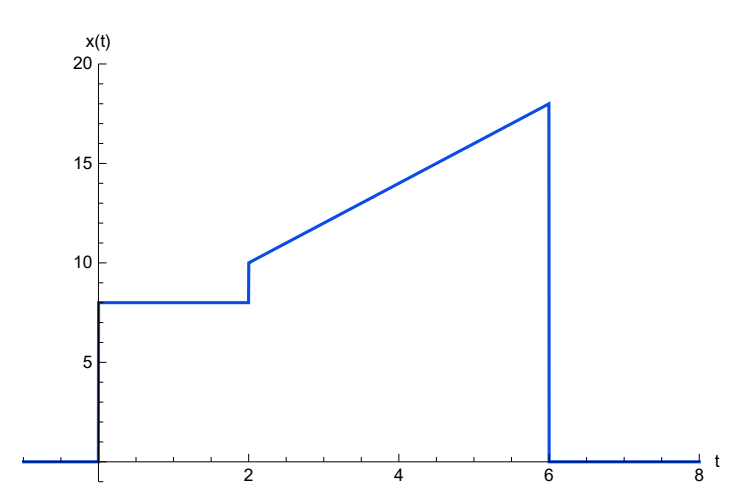


$$x=8u\left(t\right)+2u\left(t-2\right)+2r\left(t-2\right)-18u\left(t-6\right)-2r\left(t-6\right)$$


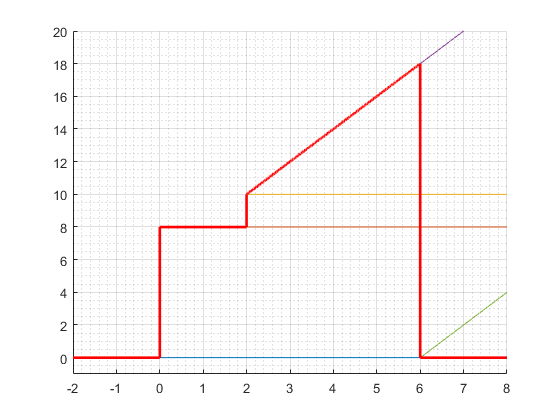

figure(2)
clf
xlim([-2,8])
ylim([-1,20])
grid on
grid minor
hold on
t = -2:0.001:8;
x = 0.*t;
plot(t,x)
pause()
x = @(t) 8*u(t);
plot(t,x(t))
pause()
x = @(t) 8*u(t)+2*u(t-2);
plot(t,x(t))
pause()
x = @(t) 8*u(t)+2*u(t-2)+2*r(t-2);
plot(t,x(t))
pause()
x = @(t) 8*u(t)+2*u(t-2)+2*r(t-2)-18*u(t-6);
plot(t,x(t))
pause()
x = @(t) 8*u(t)+2*u(t-2)+2*r(t-2)-18*u(t-6)-2*r(t-6);
plot(t,x(t),'r','LineWidth',2)


$$x=8u\left(t\right)+2u\left(t-2\right)+2r\left(t-2\right)-18u\left(t-6\right)-2r\left(t-6\right)$$


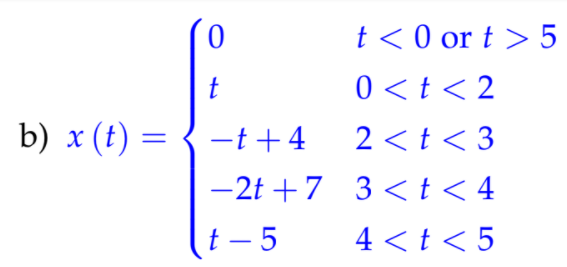

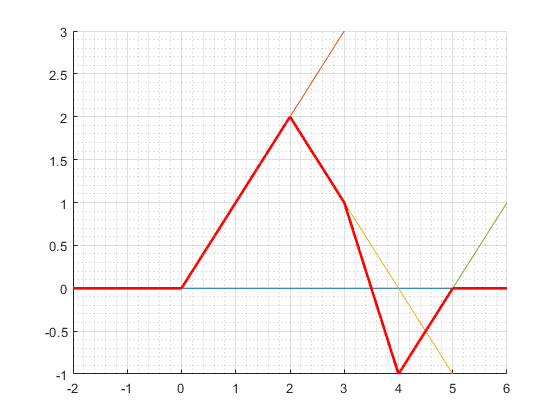

figure(3)
clf
xlim([-2,6])
ylim([-1,3])
grid on
grid minor
hold on
t = -2:0.001:6;
x = 0.*t;
plot(t,x)
pause()
x = @(t) r(t);
plot(t,x(t))
pause()
x = @(t) r(t)-2*r(t-2);
plot(t,x(t))
pause()
x = @(t) r(t)-2*r(t-2)-r(t-3); 
plot(t,x(t))
pause()
x = @(t) r(t)-2*r(t-2)-r(t-3)+3*r(t-4);
plot(t,x(t))
pause()
x = @(t) r(t)-2*r(t-2)-r(t-3)+3*r(t-4)-r(t-5);
plot(t,x(t),'r','LineWidth',2)


$$x\left(t\right)=r\left(t\right)-2r\left(t-2\right)-r\left(t-3\right)+3r\left(t-4\right)-r\left(t-5\right)$$


### Transformaciones sobre señales de singularidad


$$x_2 \left(t\right)=2x\left(t\right)$$



$$x_3 \left(t\right)=x\left(2t\right)$$



$$x_4 \left(t\right)=x\left(\frac{t}{2}\right)$$



$$x_5 \left(t\right)=x\left(-t\right)$$



$$x_6 \left(t\right)=x\left(t-2\right)$$



$$x_7 \left(t\right)=x\left(-2t-4\right)=x\left(-2\left(t+2\right)\right)$$


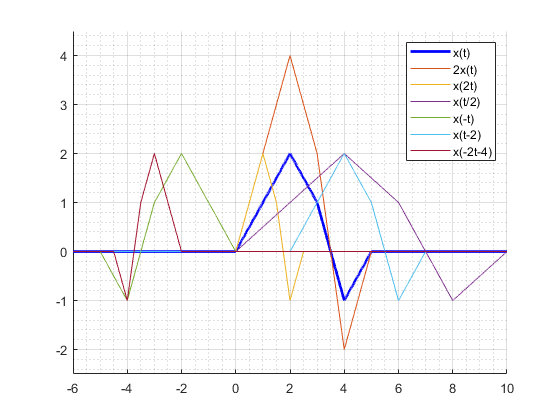

x2 =@(t) 2*x(t);
x3 =@(t) x(2*t);
x4 =@(t) x(t/2);
x5 =@(t) x(-t);
x6 =@(t) x(t-2);
x7 =@(t) x(-2*t-4);
figure(4)
clf
xlim([-6,10])
ylim([-2.5,4.5])
hold on
grid on
grid minor
t = -7:0.001:13;
plot(t,x(t),'b','LineWidth',2)
plot(t,x2(t))
plot(t,x3(t))
plot(t,x4(t))
plot(t,x5(t))
plot(t,x6(t))
plot(t,x7(t))
legend({'x(t)', '2x(t)', 'x(2t)', 'x(t/2)', 'x(-t)', 'x(t-2)', 'x(-2t-4)'})

## Muestreo (Sampling) y Sifting

En tiempo discreto el proceso es un poco más evidente. Partimos de una señal arbitraria $x\left\lbrack n\right\rbrack$:

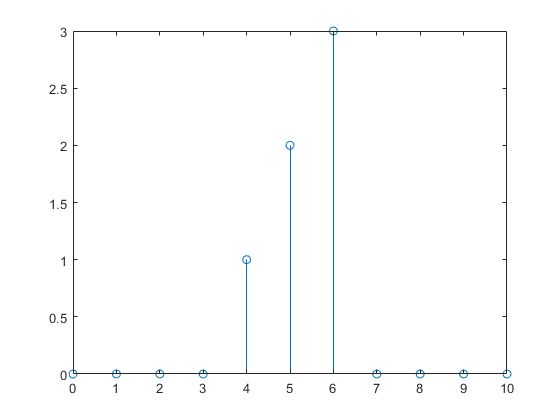

figure(5)
clf
n = 0:10;
x8 = [0 0 0 0 1 2 3 0 0 0 0];
stem(n,x8)

A partir de esta señal $x\left\lbrack n\right\rbrack$, podemos obtener muestras de ella usando la función $\delta \left\lbrack n-k\right\rbrack$:


$$x\left\lbrack n\right\rbrack \delta \left\lbrack n-k\right\rbrack =x\left\lbrack k\right\rbrack \delta \left\lbrack n-k\right\rbrack$$


A este proceso lo llamamos muestreo (sampling)

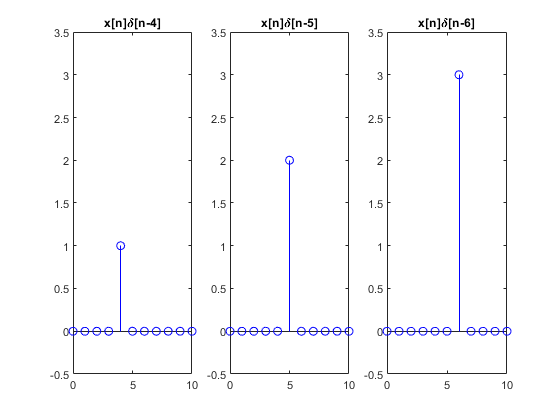

figure(6)
clf
subplot(1,3,1)
x9 = x8.*delta(n-4);
stem(n,x9,'b')
ylim([-0.5,3.5])
title('x[n]\delta[n-4]')
subplot(1,3,2)
x10 = x8.*delta(n-5);
stem(n,x10,'b')
ylim([-0.5,3.5])
title('x[n]\delta[n-5]')
subplot(1,3,3)
x11 = x8.*delta(n-6);
stem(n,x11,'b')
ylim([-0.5,3.5])
title('x[n]\delta[n-6]')

De manera inversa, podemos reconstruir exactamente una señal $x\left\lbrack n\right\rbrack$ si sumamos todas las muestras $x\left\lbrack k\right\rbrack \delta \left\lbrack n-k\right\rbrack$ que la componen:


$$x\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack \delta \left\lbrack n-k\right\rbrack$$


A este proceso lo llamamos *Sifting*

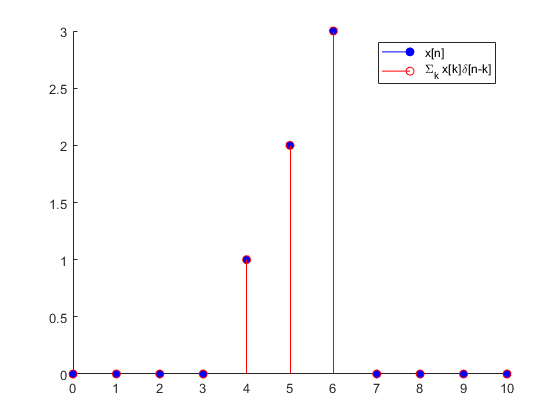

figure(7)
clf
hold on
xs = x9+x10+x11;
stem(n,x8,'b','filled')
stem(n,xs,'r')
legend({'x[n]', '\Sigma_k x[k]\delta[n-k]'})

En tiempo continuo tenemos la misma situación, con la diferencia que nuestras muestras van a estar infinitesimalmente espaciadas de modo que la suma de las mismas se ve refelajada como una integral, así tenemos que:

$x\left(t\right)\delta \left(t-t_0 \right)=x\left(t_0 \right)\delta \left(t-t_0 \right)$    Sampling

$x\left(t\right)=\int_{-\infty }^{\infty } x\left(t_0 \right)\delta \left(t-t_0 \right)\mathrm{dt}$    Sifting

En pocas palabras 

Por medio del ***Sampling*** obtengo muestras a partir de una señal y 

por medio del ***Sifting*** obtengo una señal a partir de **todas** las muestras que lo conforman.